# von Mises kappa and the Phase Locking Value/Pairwise Phase Consistency

Simulates spikes with a range of von Mises kappa synchrony parameters and computes the PPC. Generates a plot to show the relation between the two. The goal is to get an intuitive idea of their relation, which makes chosing a kappa for the simulations easier.

o=artSim;
o.duration =  60*2; % [s]  Johnson et al 2 min, Krause et al up to 40 min.
o.spikeRate = 100;  
o.spikePeak = 100e-6;
o.refractoryPeriod = 1.5e-3;
o.recordingSamplingRate = 30e3;
o.lfpAmplitude = 5e-6;
o.lfpFrequency = 10;
o.preferredPhase = 0.5*pi;
o.poisson  = true;

## Run simulation

kappa =[0:0.1:1 1.5:0.5:5];
nrKappa = numel(kappa);
nrBootstraps = 5;
ppcValue= nan(nrKappa,nrBootstraps);
for k=1:nrKappa
    o.synchrony = kappa(k);
    for bs=1:nrBootstraps
        o.simLfp;
        o.simSpikes;
        [ppcValue(k,bs)] = ppc(o.ixSpike,o.phaseLfp);
    end
end

## Generate figure

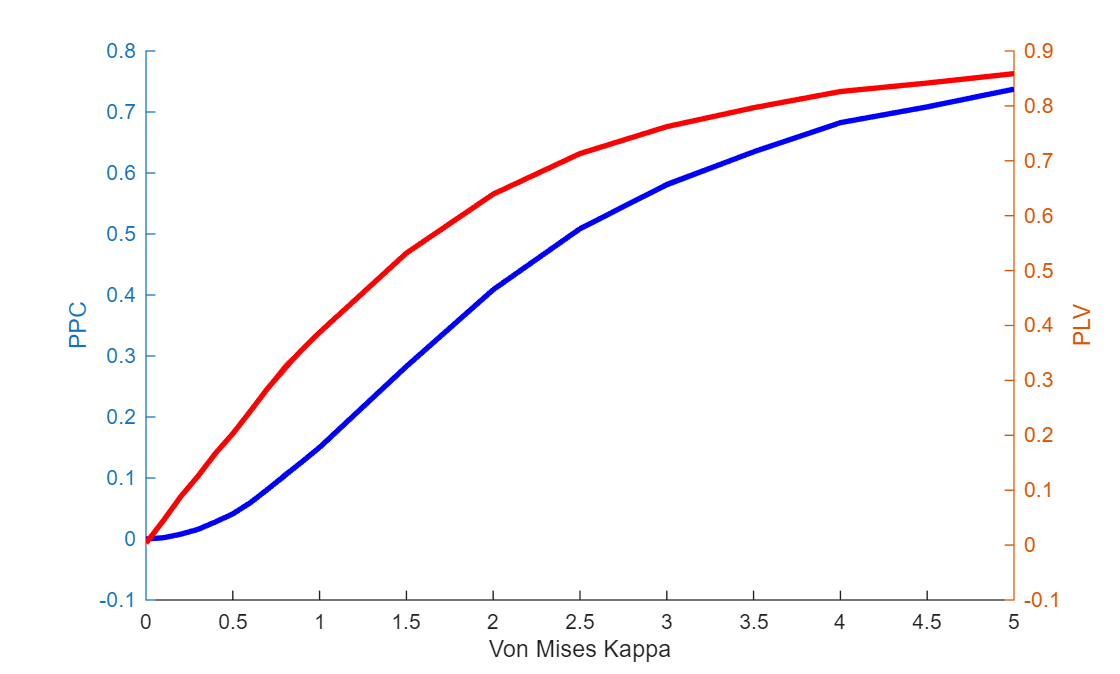

figure(1);
clf
yyaxis left
errorfill(kappa,mean(ppcValue,2)',std(ppcValue,0,2)','b');
ylabel 'PPC'
yyaxis right
ppcValue(ppcValue<0)=0;%Upward bias, but good enough
errorfill(kappa,mean(sqrt(ppcValue),2)',std(sqrt(ppcValue),0,2)','r');
ylabel 'PLV'
xlabel 'Von Mises Kappa'